# Orthorectification Parameters

**Author:     **Dr.-Ing. José Aliaga-Villagrán

**Affiliation**: Leichtweiß-Institute for Hydraulic Engineering and Water Resources

**Contact:**     j.aliaga-villagran@tu-braunschweig.de / jose.aliaga.v@protonmail.com

**Version:**     1.0 

**Date:**          2025-11-03

**Description:    **This script performs planar geometric correction (orthorectification) of the frames based on Ground Control Points (GCPs).

**Requirements:**

- Ground control points (GCPs) located at water surface elevation (min 4) ideally at corners of the field of view (FOV)

- Coordinate or distances between GCPs

**Steps:**

- Pick a calibration image (after applying lens correction distortion).

- Double-click EXACTLY 4 GCPs (any order).

- Enter the SIX pairwise distances between those 4 markers (units).

**Computes:**

- tform (image -> world)

- Rout_quad  : covers just the target quad, SAME pixel dims as input

- Rout_full  : covers the entire transformed image (full FoV)

- GSDx/GSDy  : world-units per pixel (from Rout_quad)

Saves everything to a MAT file for later batch use.

**Acknowledgments: **Parts of this script and its documentation were developed with assistance  from OpenAI's ChatGPT (GPT-5) model.

clc; close all; fprintf('=== Estimate Ortho Params (from distances) ===\n');

=== Estimate Ortho Params (from distances) ===


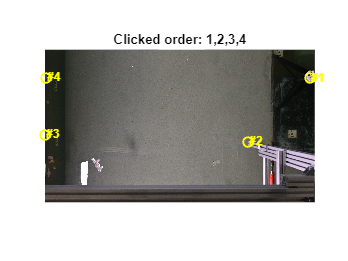


%% 1) Select ONE calibration image
[calName, calPath] = uigetfile( ...
    {'*.png;*.jpg;*.jpeg;*.tif;*.tiff','Image files'}, ...
    'Select ONE calibration image (static camera)');
if isequal(calName,0), error('Calibration image selection canceled.'); end
calibrationImagePath = fullfile(calPath, calName);
assert(exist(calibrationImagePath,'file')==2, 'File not found: %s', calibrationImagePath);

I = imread(calibrationImagePath);
[imgH, imgW, ~] = size(I);

%% 2) Units (label only)
ansUnits = inputdlg({'World units label (e.g., m, cm):'}, 'Units', 1, {'m'});
if isempty(ansUnits), error('Canceled.'); end
unitsLabel = strtrim(ansUnits{1}); if isempty(unitsLabel), unitsLabel = 'm'; end

%% 3) Pick EXACTLY 4 GCPs (zoom & pan; double-click to add a point)
hFig = figure('Name','Zoom/Pan, then double-click 4 GCP centers','Color','w', ...
              'MenuBar','none','ToolBar','none','NumberTitle','off','WindowStyle','normal');
hAx  = axes('Parent',hFig);
hIm  = imshow(I, 'Parent', hAx, 'InitialMagnification','fit'); %#ok<NASGU>
axis(hAx,'image'); hold(hAx,'on');
title(hAx, {'Scroll = ZOOM (cursor-centered)', ...
            'Left-drag = PAN   |   Double-click = place a point', ...
            'Pick EXACTLY 4 centers in ANY order. Press ESC to cancel.'}, ...
            'FontWeight','bold');
impixelinfo(hFig);
grid(hAx,'on'); hAx.GridAlpha = 0.15; hAx.MinorGridAlpha = 0.10;
set(hAx,'XMinorGrid','on','YMinorGrid','on');

% Custom zoom/pan handlers
set(hFig, 'WindowScrollWheelFcn', @(~,evt) local_zoomScroll(hAx, evt, 1.2));
set(hFig, 'WindowButtonDownFcn', @(src,~) local_panStart(src, hAx));
set(hFig, 'WindowButtonUpFcn',   @(src,~) setappdata(src,'isPanning',false));

% Point picking (double-click)
pts = zeros(4,2); picked = 0;
set(hFig,'WindowButtonDownFcn', @(src,~) local_clickHandler(src,[],hAx));
setappdata(hFig,'pickedPoints',pts);
setappdata(hFig,'pickedCount',picked);

uiwait(hFig);
if ~ishandle(hFig), error('Selection canceled (figure closed).'); end
pts    = getappdata(hFig,'pickedPoints');
picked = getappdata(hFig,'pickedCount');
delete(hFig);
if picked ~= 4, error('Need EXACTLY 4 points. You picked %d.', picked); end
imagePoints_clicked = pts;  % order = as clicked (1..4)

% Optional quick plot of clicked order
figure('Name','Clicked points (as picked)','Color','w'); imshow(I, 'InitialMagnification','fit'); hold on;
plot(imagePoints_clicked(:,1), imagePoints_clicked(:,2), 'yo','MarkerSize',8,'LineWidth',1.5);
text(imagePoints_clicked(:,1)+5, imagePoints_clicked(:,2), compose('#%d', (1:4).'), ...
     'Color','y','FontWeight','bold');
title('Clicked order: 1,2,3,4'); axis image;

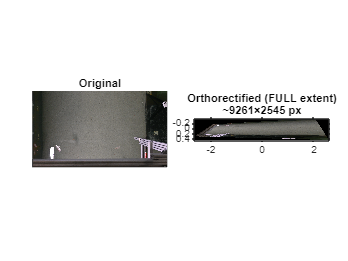


%% 4) Enter SIX pairwise distances for the SAME four points (clicked order)
prompt = { ...
  'd12 (between #1 and #2):', ...
  'd13 (between #1 and #3):', ...
  'd14 (between #1 and #4):', ...
  'd23 (between #2 and #3):', ...
  'd24 (between #2 and #4):', ...
  'd34 (between #3 and #4):'};
def = {'2.000','2.236','1.000','1.414','1.000','1.414'};  % placeholders
ansD = inputdlg(prompt, sprintf('Pairwise distances (%s)', unitsLabel), [1 50], def);
if isempty(ansD), error('Canceled.'); end

d = str2double(ansD(:));
if any(~isfinite(d) | d <= 0), error('All distances must be positive finite numbers.'); end

% Build symmetric 4x4 distance matrix
D = zeros(4);
D(1,2)=d(1); D(2,1)=d(1);
D(1,3)=d(2); D(3,1)=d(2);
D(1,4)=d(3); D(4,1)=d(3);
D(2,3)=d(4); D(3,2)=d(4);
D(2,4)=d(5); D(4,2)=d(5);
D(3,4)=d(6); D(4,3)=d(6);

% Reconstruct 2D coords via classical MDS and orient to TL–TR–BR–BL (y-up)
X = local_mds_coords_from_distances(D, 2);     % 4x2, centered
world_TL_TR_BR_BL = local_order_TL_TR_BR_BL_world(X);

% Reorder clicked image points to TL–TR–BR–BL (image coords, y-down)
img_TL_TR_BR_BL = local_reorder_img_to_world(imagePoints_clicked);

%% 5) Homography + referencing (quad coverage with SAME pixel size)
minX = min(world_TL_TR_BR_BL(:,1)); maxX = max(world_TL_TR_BR_BL(:,1));
minY = min(world_TL_TR_BR_BL(:,2)); maxY = max(world_TL_TR_BR_BL(:,2));

% Rout covering ONLY the target quad, but preserving the input pixel count
Rout_quad = imref2d([imgH, imgW], [minX, maxX], [minY, maxY]);

% Projective transform (image -> world)
tform = fitgeotrans(img_TL_TR_BR_BL, world_TL_TR_BR_BL, 'projective');

% Pixel scales (from quad mapping)
GSDx = (maxX - minX) / imgW;   % world units per pixel in X
GSDy = (maxY - minY) / imgH;   % world units per pixel in Y

%% 6) FULL-EXTENT coverage: include ALL picture information
% Map the corners of the ORIGINAL image through the transform
imgCorners = [ 1  1;  imgW 1;  imgW imgH;  1 imgH ];
[cx, cy] = transformPointsForward(tform, imgCorners(:,1), imgCorners(:,2));

% Bounding box in world space that covers the entire transformed image
Xmin = min(cx); Xmax = max(cx);
Ymin = min(cy); Ymax = max(cy);

% Optional padding (in world units)
pad = 0;  % e.g., 0.01 if units are meters
Xmin = Xmin - pad; Xmax = Xmax + pad;
Ymin = Ymin - pad; Ymax = Ymax + pad;

% Use the SAME pixel scales as the quad to size the full canvas
nCols_full = max(1, ceil((Xmax - Xmin) / GSDx));
nRows_full = max(1, ceil((Ymax - Ymin) / GSDy));
Rout_full  = imref2d([nRows_full, nCols_full], [Xmin, Xmax], [Ymin, Ymax]);

%% 7) Visual comparison — Original vs FULL-extent rectified (side-by-side)
J_full = imwarp(I, tform, 'OutputView', Rout_full, 'FillValues', 0);

figure('Name','Visual comparison','Color','w');
tiledlayout(1,2,'Padding','compact','TileSpacing','compact');

% Left: Original
nexttile;
imshow(I, 'InitialMagnification','fit'); axis image;
title('Original');

% Right: Full-extent orthorectified
nexttile;
imshow(J_full, Rout_full, 'InitialMagnification','fit'); axis image;
title(sprintf('Orthorectified (FULL extent)\n~%d×%d px', size(J_full,2), size(J_full,1)));

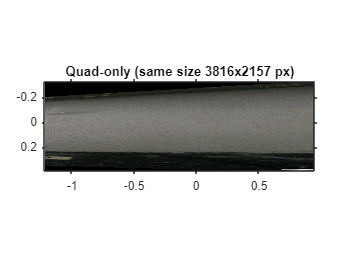


% Optional small preview of quad-only rectification
J_quad = imwarp(I, tform, 'OutputView', Rout_quad, 'FillValues', 0);
figure('Name','Quad-only preview (same pixel size as input)','Color','w');
imshow(J_quad, Rout_quad, 'InitialMagnification','fit'); axis image;
title(sprintf('Quad-only (same size %dx%d px)', imgW, imgH));


%% 8) Save parameters to MAT
[suggName, suggPath] = uiputfile('*.mat', 'Save orthorectification parameters as', ...
    fullfile(calPath, [erase(calName, {'.png','.jpg','.jpeg','.tif','.tiff'}) '_ortho_params.mat']));
if isequal(suggName,0), error('Save canceled.'); end
outMat = fullfile(suggPath, suggName);

meta = struct();
meta.scriptVersion = '1.1';
meta.dateUTC = datestr(datetime('now','TimeZone','UTC'));
meta.unitsLabel = unitsLabel;
meta.calibrationImagePath = calibrationImagePath;
meta.imageSize = [imgH imgW];
meta.clickedOrder = 'as-picked (1..4), mapped to TL,TR,BR,BL via orientation';
meta.distanceMatrix = D;
meta.notes = 'Includes Rout_quad (same size) and Rout_full (full FoV).';

save(outMat, ...
    'tform', ...
    'Rout_quad','Rout_full', ...
    'imagePoints_clicked','img_TL_TR_BR_BL', ...
    'world_TL_TR_BR_BL','D', ...
    'GSDx','GSDy','unitsLabel','meta');

fprintf('\nSaved orthorectification parameters to:\n  %s\n', outMat);


Saved orthorectification parameters to:
  O:\_EROSVSP\05_Laborversuche\Kaiwandkolk\Hafenbecken\2025\PTV\Data_Post-Processing\Orthorectification\Frame_Cal_Marker_NZ5_undist_ortho_params.mat


fprintf('Next step: batch script can choose Rout_quad or Rout_full when rectifying.\n');

Next step: batch script can choose Rout_quad or Rout_full when rectifying.



%% ============================== Local helpers =============================
function local_zoomScroll(ax, evt, base)
    if ~ishandle(ax), return; end
    pt = get(ax,'CurrentPoint'); cx = pt(1,1); cy = pt(1,2);
    xlim0 = get(ax,'XLim'); ylim0 = get(ax,'YLim');
    if cx < xlim0(1) || cx > xlim0(2) || cy < ylim0(1) || cy > ylim0(2)
        cx = mean(xlim0); cy = mean(ylim0);
    end
    s = base^(-evt.VerticalScrollCount);
    newW = (xlim0(2)-xlim0(1))/s; newH = (ylim0(2)-ylim0(1))/s;
    dxL = (cx - xlim0(1));  dyB = (cy - ylim0(1));
    scaleL = dxL/(xlim0(2)-xlim0(1)); scaleB = dyB/(ylim0(2)-ylim0(1));
    x1 = cx - newW*scaleL;  x2 = x1 + newW;
    y1 = cy - newH*scaleB;  y2 = y1 + newH;
    set(ax,'XLim',[x1 x2],'YLim',[y1 y2]);
end

function local_panStart(fig, ax)
    if ~ishandle(ax), return; end
    if ~strcmp(get(fig,'SelectionType'),'normal'), return; end
    setappdata(fig,'isPanning',true);
    setappdata(fig,'startPoint',get(ax,'CurrentPoint'));
    setappdata(fig,'startXLim',get(ax,'XLim'));
    setappdata(fig,'startYLim',get(ax,'YLim'));
    set(fig,'WindowButtonMotionFcn',@(src,~) local_panMotion(src,ax));
end

function local_panMotion(fig, ax)
    if ~ishandle(ax) || ~getappdata(fig,'isPanning'), return; end
    cp0 = getappdata(fig,'startPoint'); cp = get(ax,'CurrentPoint');
    dx = cp(1,1) - cp0(1,1); dy = cp(1,2) - cp0(1,2);
    xl0 = getappdata(fig,'startXLim'); yl0 = getappdata(fig,'startYLim');
    set(ax,'XLim',xl0 - dx,'YLim',yl0 - dy);
end

function local_clickHandler(fig, ~, ax)
    if ~ishandle(ax), return; end
    if ~strcmp(get(fig,'SelectionType'),'open') % double-click = place point
        local_panStart(fig, ax); return;
    end
    pt = get(ax,'CurrentPoint'); pos = round(pt(1,1:2));
    if any(~isfinite(pos)), return; end
    pts = getappdata(fig,'pickedPoints'); n = getappdata(fig,'pickedCount');
    if n >= 4, return; end
    n = n + 1; pts(n,:) = pos;
    plot(ax, pos(1), pos(2), 'yo', 'MarkerSize', 8, 'LineWidth', 1.5);
    text(ax, pos(1)+5, pos(2), sprintf('#%d',n), 'Color','y','FontWeight','bold');
    setappdata(fig,'pickedPoints',pts); setappdata(fig,'pickedCount',n);
    if n == 4, uiresume(fig); end
end

function X = local_mds_coords_from_distances(D, q)
% Classical MDS (Torgerson) from distances -> q-D coordinates.
    N = size(D,1);
    assert(isequal(size(D),[N N]), 'D must be square.');
    assert(all(abs(D-D.')<1e-9,'all') && all(diag(D)==0), 'D must be symmetric with zero diagonal.');
    J = eye(N) - (1/N)*ones(N);
    B = -0.5 * J * (D.^2) * J;       % double-centered Gram
    [V, S] = eig((B+B')/2);          % symmetrize for stability
    [s,ord] = sort(diag(S), 'descend'); s(s<0) = 0;
    V = V(:,ord); S = diag(s);
    X = V(:,1:q) * sqrt(S(1:q,1:q));
end

function Q = local_order_TL_TR_BR_BL_world(X)
% Reorder 4 world points to TL,TR,BR,BL (y-up).
    if size(X,1)~=4 || size(X,2)~=2, error('X must be 4x2.'); end
    c = mean(X,1);
    ang = atan2(X(:,2)-c(2), X(:,1)-c(1));
    [~,idx] = sort(ang); X = X(idx,:);
    [~, iTL] = min(X(:,2) - 0.001*X(:,1));
    X = circshift(X, -(iTL-1), 1);
    v1 = X(2,:) - X(1,:); v2 = X(3,:) - X(1,:);
    if (v1(1)*v2(2) - v1(2)*v2(1)) > 0
        X = [X(1,:); X(4,:); X(3,:); X(2,:)]; % enforce CW TL->TR->BR->BL
    end
    Q = X;
end

function P = local_reorder_img_to_world(Pclicked)
% Reorder clicked image points (1..4) to TL,TR,BR,BL (image y-down).
    if size(Pclicked,1) ~= 4, error('Expected 4 points.'); end
    P = Pclicked;
    c = mean(P,1);
    ang = atan2(P(:,2)-c(2), P(:,1)-c(1));
    [~, idx] = sort(ang); P = P(idx,:);
    [~,itop] = min(P(:,2) + 0.001*P(:,1));  % TL first (y-down)
    P = circshift(P, -(itop-1), 1);
    v1 = P(2,:) - P(1,:); v2 = P(3,:) - P(1,:);
    if (v1(1)*v2(2) - v1(2)*v2(1)) > 0, P = [P(1,:); P(4,:); P(3,:); P(2,:)]; end
end